clear;
close all;

% 1.1
% All values are entered in SI
Pn=20e3; %W
U1n=1e4; %V
U2n=230; %V
I1n=Pn/(3*U1n)

I1n = 0.6667

I2n=Pn/(3*U2n)

I2n = 28.9855

% 1.2
U1nLL=sqrt(3)*U1n

U1nLL = 1.7321e+04

U2nLL=U2n

U2nLL = 230

I1nLL=I1n

I1nLL = 0.6667

I2nLL=sqrt(3)*I2n

I2nLL = 50.2044

% 1.3
epsilon=0.04;
USC=epsilon*U1n

USC = 400

% 1.4
I2SC=I2n/epsilon

I2SC = 724.6377

% 1.5
PSC=0.2e3; %W
R1=PSC/(6*I1n^2)

R1 = 75

cosphi1SC=PSC/(3*USC*I1n)

cosphi1SC = 0.2500

QSC=PSC*sqrt(1-cosphi1SC^2)/cosphi1SC

QSC = 774.5967

Xl1=QSC/(6*I1n^2)

Xl1 = 290.4738

PNL=0.6e3;%W
cosphi1NL=0.1;
Rm=3*U1n^2/PNL

Rm = 500000

QNL=PNL*sqrt(1-cosphi1NL^2)/cosphi1NL

QNL = 5.9699e+03

Xm=3*U1n^2/QNL

Xm = 5.0252e+04

% 1.6
a=U1n/U2n;
f=50; %Hz
R2=R1/a^2

R2 = 0.0397

Xl2=Xl1/a^2

Xl2 = 0.1537

L2=Xl2/(2*pi*f)

L2 = 4.8912e-04

% 1.7
Xl1/R1

ans = 3.8730

Xm/R1

ans = 670.0252

Rm/R1

ans = 6.6667e+03

% 1.8
ZSC=USC/I1n

ZSC = 600

% 1.9
alpha=1;
eta=alpha*Pn/(alpha*Pn+PNL+alpha^2*PSC)

eta = 0.9615

% 1.10
Utr=U1n/a

Utr = 230

Ztr=1/(1/((R1+1i*Xl1)/a^2)+1/(Rm+1i*Xm))+R2+1i*Xl2

Ztr = 0.0794 + 0.3073i

Rtr=real(Ztr)

Rtr = 0.0794

Xtr=imag(Ztr)

Xtr = 0.3073

% 2.1
cosphim1n=0.8;
Pm1n=16e3;
Um1n=U2n;
Im1n=Pm1n/(3*Um1n*cosphim1n)

Im1n = 28.9855

% 2.2
Um1LL=sqrt(3)*Um1n

Um1LL = 398.3717

Im1LL=Im1n

Im1LL = 28.9855

% 2.3
cosphimSC=0.2;
UmSC=46;
PmSC=3*UmSC*Im1n*cosphimSC

PmSC = 800

R1m=PmSC/(6*Im1n^2)

R1m = 0.1587

QmSC=PmSC*sqrt(1-cosphimSC^2)/cosphimSC

QmSC = 3.9192e+03

Xl1m=QmSC/(6*Im1n^2)

Xl1m = 0.7775

PmNL=520;
Pms=104;
Pcore=PmNL-Pms

Pcore = 416

Rmm=3*Um1n^2/Pcore

Rmm = 381.4904

QmNL=Pcore*sqrt(1-cosphi1NL)/cosphi1NL

QmNL = 3.9465e+03

Xmm=3*Um1n^2/QmNL

Xmm = 40.2126

% 2.5
p=3;
n=16.333;
n1=f/p

n1 = 16.6667

sn=(n1-n)/n1

sn = 0.0200

R=Rtr+R1m

R = 0.2381

X=Xtr+Xl1m

X = 1.0848

Zst=R+1i*X

Zst = 0.2381 + 1.0848i

Zmm=1/(1/Rmm+1/(1i*Xmm))

Zmm = 4.1922 +39.7707i

Zro=R1m/sn+1i*Xl1m

Zro = 7.9271 + 0.7775i

Zn=Zst+1/(1/Zmm+1/Zro)

Zn = 7.4650 + 3.1878i

Im1=Um1n/abs(Zn)

Im1 = 28.3352

cosphi=real(Zn)/abs(Zn)

cosphi = 0.9197

% 2.6
P1=3*Um1n*Im1*cosphi

P1 = 1.7980e+04

Pcop1=3*Im1^2*R

Pcop1 = 573.3789

Pag=P1-Pcop1-Pcore

Pag = 1.6991e+04

Pcop2=sn*Pag

Pcop2 = 340.1611

Pcop=Pcop1+Pcop2

Pcop = 913.5400

Pm=Pag-Pcop2

Pm = 1.6651e+04

P0=Pm-Pms

P0 = 1.6547e+04

% 2.7
M=P0/(2*pi*n)

M = 161.2393

% 2.8
s=1;
Zrost=R1m/s+1i*Xl1m

Zrost = 0.1587 + 0.7775i

Zstart=Zst+1/(1/Zmm+1/Zrost)

Zstart = 0.3922 + 1.8475i

Istart=Um1n/abs(Zstart)

Istart = 121.7789

% 2.9
Istart/Im1

ans = 4.2978

Im1/Im1n

ans = 0.9776

% 2.10
eta=P0/P1

eta = 0.9203

% 2.11
smax=R1m/(X+Xl1m)

smax = 0.0852

Mmax=3*Um1n^2/(4*pi*n1*(X+Xl1m))

Mmax = 406.8915

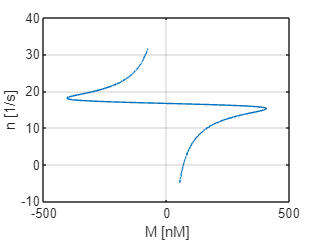

% 2.12
clear s n;
%n = 0:0.01:n1;
n = -5:0.01:n1+15;
for i=1:1:length(n)
    s=(n1-n(i))/n1;
    M(i)=Mmax*2/((s/smax)+(smax/s));
end
figure
plot(M,n);
grid on;
xlabel("M [nM]")
ylabel("n [1/s]")

% Additional task, refined Kloss equation
figure;
hold on;
plot(M,n);

sigma = (X) / Xmm;
X2 = Xl1m + (X) / (1 + sigma);
epsilon = (R) / sqrt((R)^2 + X2^2);
sm = R1m / sqrt((R)^2 + X2^2)

sm = 0.0858

Mmax = 3*Um1n^2 / (4 * pi * n1 * (1 + sigma)^2) * 1 / ((R) + sqrt((R)^2 + X2^2))

Mmax = 344.2180

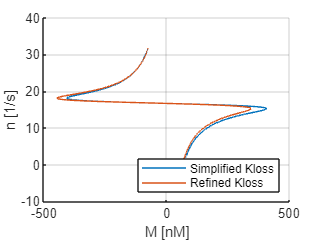

for i = 1:length(n)
    s = (n1 - n(i)) / n1;
    M(i) = Mmax * 2 * (1 + epsilon) / (s / sm + sm / s + 2 * epsilon);
end


plot(M, n);
grid on;
xlabel("M [nM]")
ylabel("n [1/s]")
legend("Simplified Kloss","Refined Kloss",'Location','southeast')